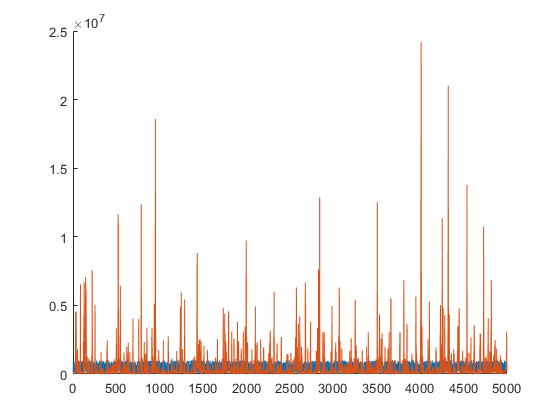

clear all
rng(1);
load decexp

figure;
hold on
plot(1000000*u)
plot(y)
hold off

u3 = u(1:3995);

u3 =     0.0866
    0.1232
    0.8775
    0.7220
    0.2297
    0.6016
    0.7071
    0.2524
    0.2079
    0.8644


u2 = u(2:3996);

u2 =     0.1232
    0.8775
    0.7220
    0.2297
    0.6016
    0.7071
    0.2524
    0.2079
    0.8644
    0.7043


u1 = u(3:3997);

u1 =     0.8775
    0.7220
    0.2297
    0.6016
    0.7071
    0.2524
    0.2079
    0.8644
    0.7043
    0.1589


y1 = y(3:3997);

y1 = 	1.0e+07 *

    0.0000
    0.0001
    0.0002
    0.0016
    0.0116
    0.0131
    0.0106
    0.0143
    0.0175
    0.0108


y2 = y(2:3996);

y2 = 	1.0e+07 *

    0.0000
    0.0000
    0.0001
    0.0002
    0.0016
    0.0116
    0.0131
    0.0106
    0.0143
    0.0175


y3 = y(1:3995);

y3 = 	1.0e+07 *

    0.0000
    0.0000
    0.0000
    0.0001
    0.0002
    0.0016
    0.0116
    0.0131
    0.0106
    0.0143



featurez= [u3 u2 u1 y1 y2 y3];

featurez = 	1.0e+07 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0002    0.0001    0.0000
    0.0000    0.0000    0.0000    0.0016    0.0002    0.0001
    0.0000    0.0000    0.0000    0.0116    0.0016    0.0002
    0.0000    0.0000    0.0000    0.0131    0.0116    0.0016
    0.0000    0.0000    0.0000    0.0106    0.0131    0.0116
    0.0000    0.0000    0.0000    0.0143    0.0106    0.0131
    0.0000    0.0000    0.0000    0.0175    0.0143    0.0106
    0.0000    0.0000    0.0000    0.0108    0.0175    0.0143



zeta = y(4:3998)

zeta = 	1.0e+07 *

    0.0001
    0.0002
    0.0016
    0.0116
    0.0131
    0.0106
    0.0143
    0.0175
    0.0108
    0.0022



u3t = u(4001:4995);

u3t =     0.6807
    0.7019
    0.5466
    0.6809
    0.7949
    0.8873
    0.9876
    0.9078
    0.8254
    0.7334


u2t = u(4002:4996);

u2t =     0.7019
    0.5466
    0.6809
    0.7949
    0.8873
    0.9876
    0.9078
    0.8254
    0.7334
    0.9269


u1t = u(4003:4997);

u1t =     0.5466
    0.6809
    0.7949
    0.8873
    0.9876
    0.9078
    0.8254
    0.7334
    0.9269
    0.7215


y1t = y(4003:4997);

y1t = 	1.0e+07 *

    0.1482
    0.2906
    0.4039
    0.3915
    0.7246
    1.1289
    1.4057
    1.7093
    2.4186
    2.0013


y2t = y(4002:4996);

y2t = 	1.0e+07 *

    0.0978
    0.1482
    0.2906
    0.4039
    0.3915
    0.7246
    1.1289
    1.4057
    1.7093
    2.4186


y3t = y(4001:4995);

y3t = 	1.0e+07 *

    0.0325
    0.0978
    0.1482
    0.2906
    0.4039
    0.3915
    0.7246
    1.1289
    1.4057
    1.7093



tfeaturez= [u3t u2t u1t y1t y2t y3t];

tfeaturez = 	1.0e+07 *

    0.0000    0.0000    0.0000    0.1482    0.0978    0.0325
    0.0000    0.0000    0.0000    0.2906    0.1482    0.0978
    0.0000    0.0000    0.0000    0.4039    0.2906    0.1482
    0.0000    0.0000    0.0000    0.3915    0.4039    0.2906
    0.0000    0.0000    0.0000    0.7246    0.3915    0.4039
    0.0000    0.0000    0.0000    1.1289    0.7246    0.3915
    0.0000    0.0000    0.0000    1.4057    1.1289    0.7246
    0.0000    0.0000    0.0000    1.7093    1.4057    1.1289
    0.0000    0.0000    0.0000    2.4186    1.7093    1.4057
    0.0000    0.0000    0.0000    2.0013    2.4186    1.7093



tlabels = y(4004:4998)

tlabels = 	1.0e+07 *

    0.2906
    0.4039
    0.3915
    0.7246
    1.1289
    1.4057
    1.7093
    2.4186
    2.0013
    0.4441


clear u y

[N, d]=size(featurez); 

nn = 2;  %degree B-spline
knotintervals = 8;
nnn= knotintervals+nn;

bs = bspline([0:nn+1]);
M = flipud(bs.coefs)';

knotdist = 1/knotintervals;

indexes = floor(featurez/knotdist)+1;
indexes(indexes>knotintervals)= knotintervals;

inputs = (featurez/knotdist)-indexes+1;
for i=1:d
bn = inputs(:,i).^[nn:-1:0]*M;

u{i} = zeros(N,nnn);
for ii=1:N
   u{i}(ii,indexes(ii,i):indexes(ii,i)+nn) = bn(ii,:);
end
end



Pcount = (nnn)^d

Pcount = 1000000

% gamma=((N/Pcount^4))
% gamma=0

R = nnn^2;
R=8;
r=R*ones(1,d+1);

% %  r(d-1)=nnn^2;
r(1) = 1;  r(2)=nnn;  r(d)=nnn; r(d+1)=1;
disp(r)

     1    10     8     8     8    10     1



n=nnn*ones(1,d);

init=cell(1,d);
    for i=1:d
        init{i}.core=randn(r(i),n(i),r(i+1));
        init{i}.core=(init{i}.core/(norm(init{i}.core(:))));
        init{i}.r(1)=r(i);
        init{i}.n = n(i);
        init{i}.r(2)=r(i+1);
    end


   
    
% function TN=tencom(y,u,r,init,varargin)

% 2018, Ching-Yun KO

% N=size(u{1},1);
% d=size(u,2);                 

for i=1:d
    n(i)=size(u{i},2);
end
  

for i=1:d
    TN.core{i}=init{i}.core;
    TN.n(i,:)=[init{i}.r(1),init{i}.n,init{i}.r(2)];
end


Vp=cell(1,d);
Vm=cell(1,d);

Vm{1}=ones(N,1);
Vp{d}=ones(N,1);

% initialize right-orthonormal cores with prescribed TN ranks
for i=d:-1:2
    Vp{i-1}=dotkron(Vp{i},u{i})*reshape(permute(TN.core{i},[3 2 1]),[r(i+1)*n(i),r(i)]); 
end

difforder=2

difforder = 2

P = diff(eye(nnn),difforder);
PP = P'*P;

res1=[];
res2=[];
MAXITR = 10*d;

itr=1;                          % counts number of iterations
ltr=1;                          % flag that checks whether we sweep left to right
sweepindex=1;                   % index that indicates which TT core will be updated

gamma=0;
 tic
bbb=1;
% while itr<2 || ((e(itr) < e(itr-1)) && (itr < MAXITR) && e(itr) > THRESHOLD)
while itr<2 ||  (itr < MAXITR )
%     ---------------------updateTT-----------------;
            
nselect = floor(((itr+1)/MAXITR)^4*(N));
dataselect = randperm((N),nselect);
dataselect = 1:N;
    %         % first construct the linear subsystem matrix
        A=dotkron(Vm{sweepindex}(dataselect,:),u{sweepindex}(dataselect,:),Vp{sweepindex}(dataselect,:));
%         g=pinv(A'*A)*(A'*y(dataselect,:));
     
%        
                   
%         -------------------difference penalty 
        for j=1:d
        Csize = TN.n(j,:);
        
        Dm = reshape(permute(TN.core{j}, [2 1 3]), [Csize(2) Csize(1)*Csize(3)]);
        mDDm = reshape(Dm'*Dm, [Csize(1) Csize(3) Csize(1) Csize(3)]);
        DD{j} = reshape(permute(mDDm,[1 3 2 4]), [Csize(1)*Csize(1) Csize(3)*Csize(3)]);
        PD = P*Dm;
        DPPD = reshape(PD'*PD, [Csize(1) Csize(3) Csize(1) Csize(3)]);
        DWD{j} = reshape(permute(DPPD,[1 3 2 4]), [Csize(1)*Csize(1) Csize(3)*Csize(3)]);
        eyez{j}= reshape(eye(Csize(1)), [Csize(1)^2 1]);
        eyep{j}= reshape(eye(Csize(2)), [Csize(2)^2 1]);
        end
        eyez{d+1}=1;
        
        for p= 1:d
            Dsize = TN.n(sweepindex,:);   
                if sweepindex==p
                    D1 = eyez{sweepindex};
                    D2 = PP(:);
                    D3 = eyez{sweepindex+1};
                elseif sweepindex<p
                    D1 = eyez{sweepindex};  
                    D2 = eyep{sweepindex};   
                    D3= DWD{p}*eyez{p+1};           
                    for it=(p-1):-1:(sweepindex+1)               
                        D3 = DD{it}*D3;
                    end                               
                elseif sweepindex>p   
                    D1= eyez{p}'*DWD{p};
                    for it=(p+1):(sweepindex-1)               
                        D1 = D1*DD{it};
                    end
                    D1=D1';
                    D2 = eyep{sweepindex};   
                    D3= eyez{sweepindex+1}; 
                end
          
            WW = kron(D3, kron(D2, D1));
            Wtemp = permute(reshape(WW, [Dsize(1) Dsize(1) Dsize(2) Dsize(2) Dsize(3) Dsize(3)]), [1 3 5 2 4 6]);
            W{p} = reshape(Wtemp, [prod(Dsize) prod(Dsize)]); 
        end
        WWW = W{1};
        for s =2:d
            WWW = WWW + W{s};
        end
%         ----------------------- 
        D = eye(r(sweepindex)*(n(sweepindex))*r(sweepindex+1));         

        g=pinv(A'*A + gamma*WWW + 0.000000001*D)*(A'*zeta(dataselect,:));

        if ltr
            % left-to-right sweep, generate left orthogonal cores and update vk1
            TN.core{sweepindex}=reshape(g,[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            [Q,R]=qr(reshape(g,[r(sweepindex)*(n(sweepindex)),r(sweepindex+1)])); 
            TN.core{sweepindex}=reshape(Q(:,1:r(sweepindex+1)),[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            TN.core{sweepindex+1}=reshape(R(1:r(sweepindex+1),:)*reshape(TN.core{sweepindex+1},[r(sweepindex+1),(n(sweepindex+1))*r(sweepindex+2)]),[r(sweepindex+1),n(sweepindex+1),r(sweepindex+2)]);
            Vm{sweepindex+1}=dotkron(Vm{sweepindex},u{sweepindex})*reshape(TN.core{sweepindex},[r(sweepindex)*n(sweepindex),r(sweepindex+1)]); % N x r_{i}
        else
            % right-to-left sweep, generate right orthogonal cores and update vk2
            TN.core{sweepindex}=reshape(g,[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            [Q,R]=qr(reshape(g,[r(sweepindex),(n(sweepindex))*r(sweepindex+1)])'); 
            TN.core{sweepindex}=reshape(Q(:,1:r(sweepindex))',[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            TN.core{sweepindex-1}=reshape(reshape(TN.core{sweepindex-1},[r(sweepindex-1)*(n(sweepindex-1)),r(sweepindex)])*R(1:r(sweepindex),:)',[r(sweepindex-1),n(sweepindex-1),r(sweepindex)]);
            Vp{sweepindex-1}=dotkron(Vp{sweepindex},u{sweepindex})*reshape(permute(TN.core{sweepindex},[3 2 1]),[r(sweepindex+1)*n(sweepindex),r(sweepindex)]); % N x r_{i-1}    

        end
    
   %     ---------------------updatesweep-----------------; 
     
                if ltr
                    sweepindex=sweepindex+1;
                    if sweepindex== d                
                        ltr=0;
                        timer=toc;
                    end
                else
                    sweepindex=sweepindex-1;
                    if sweepindex== 1                
                        ltr=1;
                        timer=toc;
                    end
                end
    
    
        % only check residual after 1 half sweep
        if (sweepindex==d) || (sweepindex==1) % half a sweep
            
            res1(itr)=norm(A*g-zeta(dataselect,:))^2/(nselect); % check residual
            res2(itr)=1*(g'*g);
           
            if (itr>4)
%                 if (res1(itr)<1) || (abs(res1(itr)-res1(itr-2))<1)
%                  disp(res1(itr))
%                  break;
%                  end
            end
            
            itr=itr+1; %update iteration
            
            disp(["iteration:" itr timer])
        end   

        
end  

    "iteration:"    "2"    "0.60321"

    "iteration:"    "3"    "1.2824"

    "iteration:"    "4"    "2.0043"

    "iteration:"    "5"    "2.6296"

    "iteration:"    "6"    "3.1108"

    "iteration:"    "7"    "3.6521"

    "iteration:"    "8"    "4.097"

    "iteration:"    "9"    "4.5576"

    "iteration:"    "10"    "5.0166"

    "iteration:"    "11"    "5.5042"

    "iteration:"    "12"    "5.9871"

    "iteration:"    "13"    "6.4517"

    "iteration:"    "14"    "6.9422"

    "iteration:"    "15"    "7.4296"

    "iteration:"    "16"    "7.885"

    "iteration:"    "17"    "8.4418"

    "iteration:"    "18"    "9.2518"

    "iteration:"    "19"    "9.7585"

    "iteration:"    "20"    "10.2805"

    "iteration:"    "21"    "10.7495"

    "iteration:"    "22"    "11.3634"

    "iteration:"    "23"    "11.8677"

    "iteration:"    "24"    "12.394"

    "iteration:"    "25"    "12.9397"

    "iteration:"    "26"    "13.4808"

    "iteration:"    "27"    "14.0768"

    "iteration

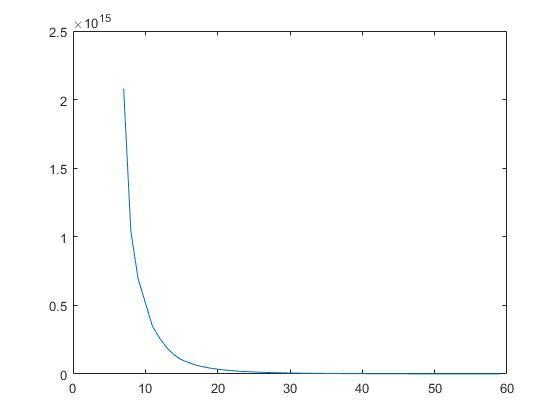

plot(res1)

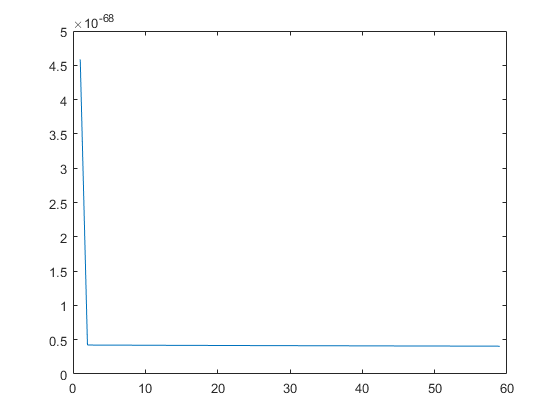

plot(res2)


[Nt, dt]=size(tfeaturez);

indexes = floor(tfeaturez/knotdist)+1;
indexes(indexes>knotintervals)= knotintervals;

inputs = (tfeaturez/knotdist)-indexes+1;

for i=1:dt
bn = inputs(:,i).^[nn:-1:0]*M;

ut{i} = zeros(Nt,nnn);
for ii=1:Nt
   ut{i}(ii,indexes(ii,i):indexes(ii,i)+nn) = bn(ii,:);
end
end

% [N, d]=size(featurez);

output=zeros(Nt,1);

G = TN.core;

for i = 1:length(G)
Gsize = [Nt size(G{i},1)  size(G{i},3)];
tempz = reshape(ut{i}*unfold(G{i},2), Gsize);
V{i} = permute(tempz, [2 3 1]);
end

output= zeros(Nt,1);

for jj=1:Nt   
f = (V{1});
f=1;
for i = 1:length(G)
f = f*V{i}(:,:,jj);
end
output(jj)=f';
end



% [tlabelz, id] = sort(tlabels);
tlabelz = tlabels;
outputsrt = output;

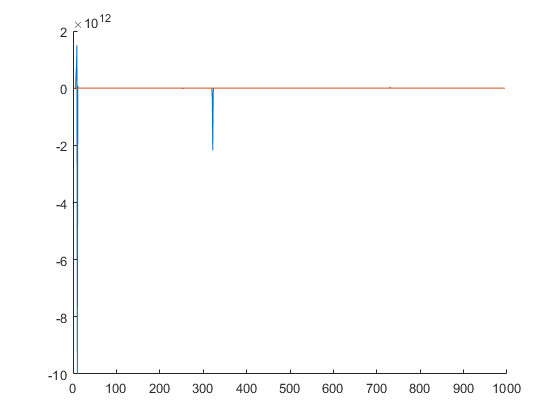



figure
hold on
plot(outputsrt)
plot(tlabelz)
hold off

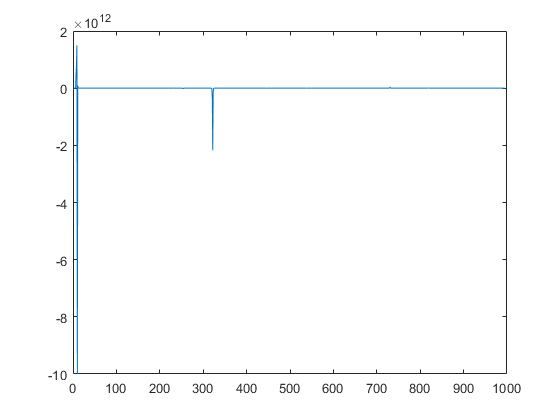

erboi = (outputsrt-tlabelz);
plot(erboi)

pererror = sum(abs(erboi))/Nt

pererror = 1.5765e+10

relerror = sum(abs(erboi)/sum(abs(tlabelz)))

relerror = 2.3276e+04

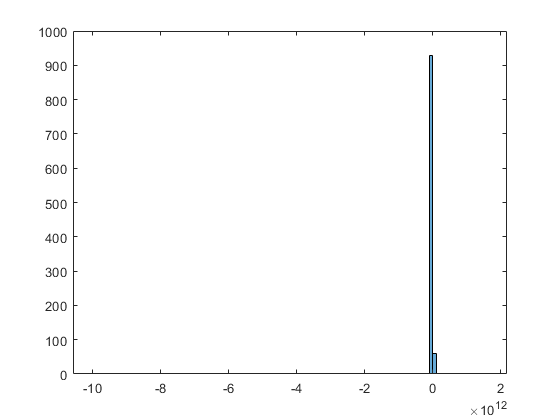

histogram((erboi)')


% % -------
% Vp=cell(1,d);
% Vm=cell(1,d);
% 
% Vm{1}=ones(N,1);
% Vp{d}=ones(N,1);
% 
% % initialize right-orthonormal cores with prescribed TN ranks
% for i=d:-1:2
%     Vp{i-1}=dotkron(Vp{i},u{i})*reshape(permute(TN.core{i},[3 2 1]),[r(i+1)*n(i),r(i)]); 
% end

% 
% difforder=2
% P = diff(eye(nnn),difforder)
% PP = P'*P
% 
% sweepindex=4
% tic
% for j=1:d
% Csize = TN.n(j,:);
% 
% Dm = reshape(permute(G{j}, [2 1 3]), [Csize(2) Csize(1)*Csize(3)]);
% mDDm = reshape(Dm'*Dm, [Csize(1) Csize(3) Csize(1) Csize(3)]);
% DD{j} = reshape(permute(mDDm,[1 3 2 4]), [Csize(1)*Csize(1) Csize(3)*Csize(3)]);
% PD = P*Dm;
% DPPD = reshape(PD'*PD, [Csize(1) Csize(3) Csize(1) Csize(3)]);
% DWD{j} = reshape(permute(DPPD,[1 3 2 4]), [Csize(1)*Csize(1) Csize(3)*Csize(3)]);
% eyez{j}= reshape(eye(Csize(1)), [Csize(1)^2 1]);
% eyep{j}= reshape(eye(Csize(2)), [Csize(2)^2 1]);
% end
% eyez{d+1}=1;
% 
% for p= 1:d
%     Dsize = TN.n(sweepindex,:);   
%         if sweepindex==p
%             D1 = eyez{sweepindex};
%             D2 = PP(:);
%             D3 = eyez{sweepindex+1};
% 
%         elseif sweepindex<p
%             D1 = eyez{sweepindex};  
%             D2 = eyep{sweepindex};   
%             D3= DWD{p}*eyez{p+1};           
%             for it=(p-1):-1:(sweepindex+1)               
%                 D3 = DD{it}*D3;
%             end                        
%          
%         elseif sweepindex>p   
%             D1= eyez{p}'*DWD{p};
%             for it=(p+1):(sweepindex-1)               
%                 D1 = D1*DD{it};
%             end
%             D1=D1';
%             D2 = eyep{sweepindex};   
%             D3= eyez{sweepindex+1}; 
% 
%         end
%     
%     WW = kron(D3, kron(D2, D1));
%     Wtemp = permute(reshape(WW, [Dsize(1) Dsize(1) Dsize(2) Dsize(2) Dsize(3) Dsize(3)]), [1 3 5 2 4 6]);
%     W{p} = reshape(Wtemp, [prod(Dsize) prod(Dsize)]);
%     
% end
% 
% WWW = W{1};
% for s =2:d
%     WWW = WWW + W{s};
% end
% 
% imagesc(WWW)
% % imagesc(W{d})
% toc
% 
% 
% % 
% % 
% % W =  permute(reshape(WW, c1 c1 c2 c2 c3 c3), [1 3 5 2 4 6]
% % reshape(W, [c1*c2*c3 c4*c5*c6])

% 
% new = kron([2 2 2]',[1 2 3]')
% lef = [1 2 3]
% mid =[1 2 3; 4 5 6; 7 8 9]
% right =[2 2 2]'
% lef*mid *right
% 
% new(:)'*mid(:)
% 